DATA SIMULATIONS, HYPOTHESIS TESTING AND STATISTICAL ANALYSIS OF A STUDY DATA 

In a computer simulation model for a network of 100 Geiger counters:

Counters are independent from each other. Each counter reports the number of radio-active particles detected in a fixed time interval, t=10 seconds. Radio-active particles can be assumed to be detected independently from each other at a constant rate of r=0.4 per second (1/second) at all counter locations. The goal of the simulation model is to generate the cumulative count of detected particles for 10 second time intervals, that is to say the sum of particle detections across all sensors.

SIMULATION

Simulate1,000 samples of the cumulative count across the network,choosing and justifying the correct probability distribution for the number of particles detected by each Geiger counter. 

Plot the resulting empirical distribution of cumulative counts and the corresponding empirical cumulative density function, CDF (1 figure, multiple panels are allowed).

% The 10 possible outcomes per counter follow a binomial distribution
% given that at each second, the counter either detects a radio-active particle or 
% it doesn't, i.e. outcome is '0 or 1'. We have also been given the probability 
% an outcome of 1, which is 0.4

pd = makedist("Binomial", "N", 10, "p", 0.4)

pd =   BinomialDistribution

  Binomial distribution
    N =  10
    p = 0.4


outcomes = 0:1:10

outcomes =      0     1     2     3     4     5     6     7     8     9    10


%generating 1000 samples of cumulative count of the outcomes

rng('default') % fix the random seed
S = 100 

S = 100

sampl = random(pd,1000,S) % in order to generate 100 outcomes in 1000 places 

sampl =      3     7     6     4     4     6     7     3     4     1     5     2     2     3     5     7     6     5     2     5     2     5     2     4     3     4     2     5     3     3     5     6     0     3     5     5     7     4     5     4     6     1     3     4     3     5     1     4     4     6
     2     6     4     4     2     2     4     3     2     3     5     4     6     2     3     4     5     2     7     3     5     4     5     5     2     7     3     3     6     4     5     2     4     5     2     5     3     6     2     2     3     2     3     7     5     4     5     2     7     2
     5     3     5     2     2     3     1     4     6     6     4     6     5     3     6     3     3     4     5     3     4     7     4     4     2     4     5     4     2     6     6     4     5     3     4     6     3     6     5     1     7     3     6     4     5     3     3     3     5     3
     4     5     6     3     3     3     3     3     4     5     2     4     4     3     

cum_counts = sum(sampl,2) %1000 samples of cumulative count of the outcomes

cum_counts =    406
   383
   403
   377
   388
   431
   428
   384
   399
   411




%Plot of resulting empirical distribution of cumulative counts 
%and empirical cumulative density function, CDF 

[binom_ecdf, x] = ecdf(cum_counts); %Empirical CDF
binom_ecdf

binom_ecdf =          0
    0.0010
    0.0020
    0.0030
    0.0050
    0.0060
    0.0080
    0.0100
    0.0110
    0.0170


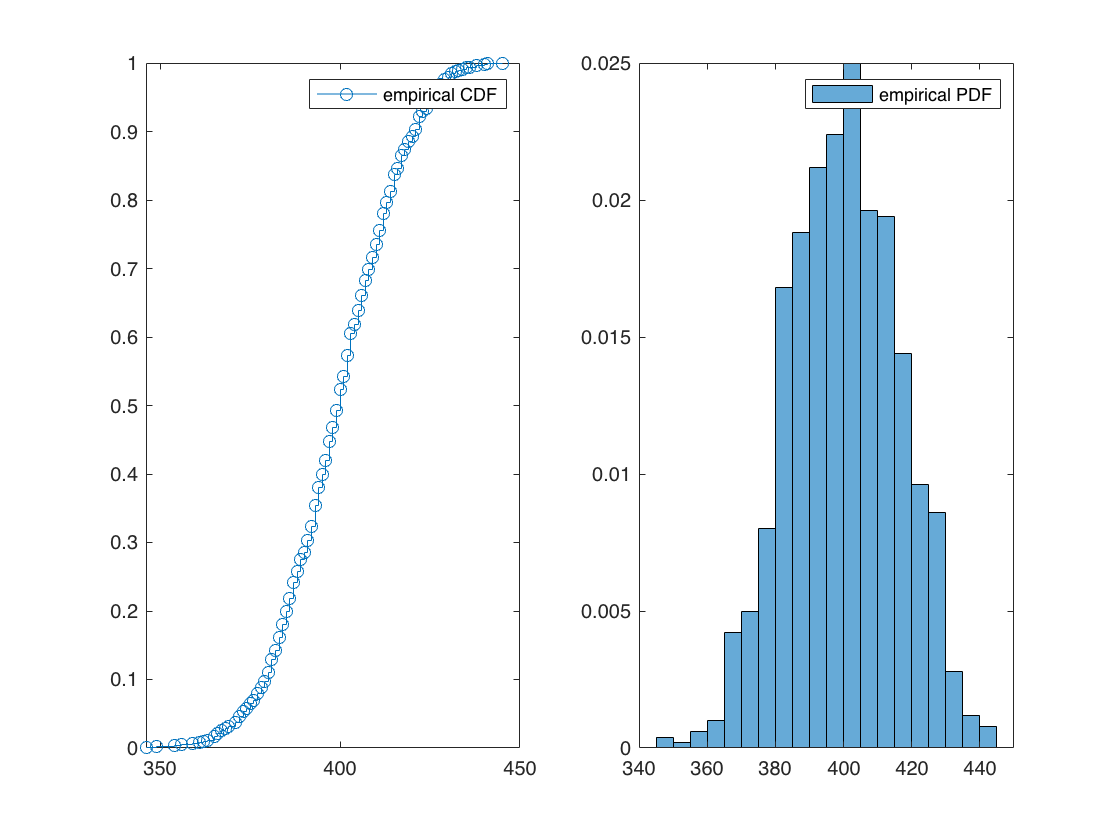


clf
subplot(1,2,1)
stairs(x, binom_ecdf, 'o-') %Empirical CDF plot
legend('empirical CDF')

subplot(1,2,2)
binom_epmf = histogram(cum_counts, 'normalization', 'pdf'); % empirical distribution of cumulative counts
legend('empirical PDF')

HYPOTHESIS TESTING 

Using Simulated data above, test the hypothesis that the cumulative count across the network is larger than 400 detected particles in a 10 second interval at a significance level of 5%. 

% Given unknown population variance, and our avaialble parameters
%such as mean and standard deviation. we will do a one-tailed t-test 

q0 = 400; %cum-sum is equal to or less than 400 
mu = q0;
observation = mean(cum_counts) %using simulated data from 1a as our observation 

observation = 399.6480

n = 1000; %length cum_counts
sigma = std(cum_counts) / n^0.5

sigma = 0.5059

tstat = (observation - mu)/ sigma

tstat = -0.6958

r = n - 1

r = 999


pval = 1 - tcdf(tstat, r)

pval = 0.7566

alpha = 0.05

alpha = 0.0500

[h, p, ci, stats] = ttest(cum_counts, mu, 'alpha', alpha, 'tail', 'right')

h = 0

p = 0.7566

ci =   398.8151
       Inf


stats = struct with fields:
    tstat: -0.6958
       df: 999
       sd: 15.9987



%the probability of obtaining a cumulative sum of 400 or above under the null hypothesis 
% is far greater than our significance level 0.05. Thus, we do not
%have enough evidence to reject the null that our cumulative sum is less than 400 . 

STATISTICAL ANALYSIS 

The file, 'burning_experiment.txt' contains a data set from controlled burning experiments on 25 commercially available scented candle brands. In the experiments the amount of a poisonous gas (in milligram, mg) emitted for each candle brand was recorded alongside the amount (in mg) of two ingredients they contain. Use a statistical analysis of this data to discuss how this experiment can be used to investigate the effect of each ingredient on poisonous gas emission and to make predictions about gas emission. Make suggestions for how to improve the experiment. In your discussion, show evidence for the statements you make (1 figure, multiple panels are allowed). This data is hypothetical.

Read in the data from .txt file 

% Read the data in the txt file and convert to matrix, then table 
fileID = fopen('burning_experiment.txt');
formatSpec = '%f %f %f'; %3 columns seperated by space 
N = 1; %The first header line is 1
file = textscan(fileID,formatSpec,'HeaderLines',N,'Delimiter',' '); %delimiter is the element that seperates the columns and that would be space ' '
fclose(fileID);

tempData= cell2mat(file); %%convert the cell data to matrix form and populate the different variables
C1 = tempData(1:end,1);
C2 = tempData(1:end,2);
C3 = tempData(1:end,3);

candles = array2table(tempData) %convert matrix to table 

candles = 25×3 table
    tempData1    tempData2    tempData3
    _________    _________    _________

      14.1         0.86         13.6   
        16         1.06         16.6   
      29.8         2.03         23.5   
         8         0.67         10.2   
       4.1          0.4          5.4   
        15         1.04           15   
       8.8         0.76            9   
      12.4         0.95         12.3   
      16.6         1.12         16.3   
      14.9         1.02         15.4   
      13.7         1.01           13   
      15.1          0.9         14.4   
       7.8         0.57           10   
      11.4         0.78         10.2   
         9         0.74          9.5   
         1         0.13          1.5   


candles.Properties.VariableNames = {'Ingredient1' 'Ingredient2' 'PoisonousGas'}

candles = 25×3 table
    Ingredient1    Ingredient2    PoisonousGas
    ___________    ___________    ____________

       14.1           0.86            13.6    
         16           1.06            16.6    
       29.8           2.03            23.5    
          8           0.67            10.2    
        4.1            0.4             5.4    
         15           1.04              15    
        8.8           0.76               9    
       12.4           0.95            12.3    
       16.6           1.12            16.3    
       14.9           1.02            15.4    
       13.7           1.01              13    
       15.1            0.9            14.4    
        7.8           0.57              10    
       11.4           0.78            10.2    
          9           0.74             9.5    
          1           0.13             1.5    


candles

candles = 25×3 table
    Ingredient1    Ingredient2    PoisonousGas
    ___________    ___________    ____________

       14.1           0.86            13.6    
         16           1.06            16.6    
       29.8           2.03            23.5    
          8           0.67            10.2    
        4.1            0.4             5.4    
         15           1.04              15    
        8.8           0.76               9    
       12.4           0.95            12.3    
       16.6           1.12            16.3    
       14.9           1.02            15.4    
       13.7           1.01              13    
       15.1            0.9            14.4    
        7.8           0.57              10    
       11.4           0.78            10.2    
          9           0.74             9.5    
          1           0.13             1.5    


Plot scatterplot for Exploratory Data Analysis 


x1 = candles.("Ingredient1")

x1 =    14.1000
   16.0000
   29.8000
    8.0000
    4.1000
   15.0000
    8.8000
   12.4000
   16.6000
   14.9000


x2 = candles.("Ingredient2")

x2 =     0.8600
    1.0600
    2.0300
    0.6700
    0.4000
    1.0400
    0.7600
    0.9500
    1.1200
    1.0200


y = candles.("PoisonousGas")

y =    13.6000
   16.6000
   23.5000
   10.2000
    5.4000
   15.0000
    9.0000
   12.3000
   16.3000
   15.4000


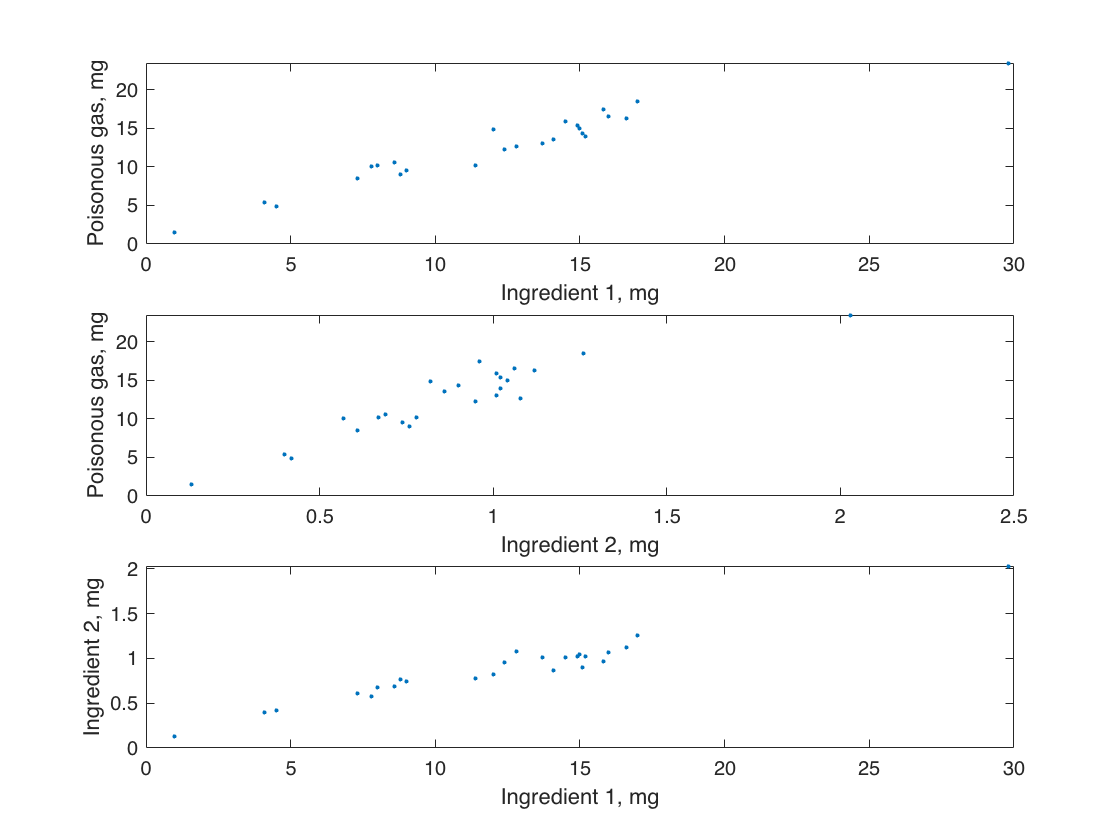


clf
subplot(3,1,1)
plot(x1, y, '.')
xlabel('Ingredient 1, mg')
ylabel('Poisonous gas, mg')

subplot(3,1,2)
plot(x2, y, '.')
xlabel('Ingredient 2, mg')
ylabel('Poisonous gas, mg')

subplot(3,1,3)
plot(x1, x2, '.')
xlabel('Ingredient 1, mg')
ylabel('Ingredient 2, mg') 

%scatterplot shows a linear relationship between predictors and response,
%as well as between predictors.

Linear regression modelling and evaluation of model performances 


%Given the multiple predictors, I will conduct a multiple linear regression model.
%I will also explore which model is best by fitting a full model with all
%predictors and other models with one predictor each 
m1 = fitlm(candles, 'PoisonousGas~Ingredient1+Ingredient2')

m1 = Linear regression model:
    PoisonousGas ~ 1 + Ingredient1 + Ingredient2

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)     3.0896     0.84377      3.6617     0.0013714
    Ingredient1    0.96247     0.23666      4.0668    0.00051241
    Ingredient2    -2.6463      3.7872    -0.69874       0.49204


Number of observations: 25, Error degrees of freedom: 22
Root Mean Squared Error: 1.41
R-squared: 0.919,  Adjusted R-Squared: 0.911
F-statistic vs. constant model: 124, p-value = 1.04e-12

    %The t-tests here suggest that the effect of Ingredient 2 on response is most likely zero (p-value ~0.5). 
    % We are not rejecting null hypothesis that beta2 = 0. 
    %In the case of Ingredient 1, we will reject the null hypothesis that beta1 = 0 given the low enough p value. 
    %Thus, the effect of ingredient 1 on response is non-zero. 

m2 = fitlm(candles, 'PoisonousGas~Ingredient1') %Lowest RMSE, F-test p-value, second lowest R-squared

m2 = Linear regression model:
    PoisonousGas ~ 1 + Ingredient1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     2.7433     0.67521    4.0629    0.00048117
    Ingredient1    0.80098     0.05032    15.918    6.5522e-14


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 1.4
R-squared: 0.917,  Adjusted R-Squared: 0.913
F-statistic vs. constant model: 253, p-value = 6.55e-14

    %Effect of Ingredient 1 on response are non zero(0.80098), ttest suggests.

m3 = fitlm(candles, 'PoisonousGas~Ingredient2')

m3 = Linear regression model:
    PoisonousGas ~ 1 + Ingredient2

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     1.6647     0.9936    1.6754        0.1074
    Ingredient2     12.395     1.0542    11.759    3.3117e-11


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 1.83
R-squared: 0.857,  Adjusted R-Squared: 0.851
F-statistic vs. constant model: 138, p-value = 3.31e-11

    %Effect of Ingredient 2 on response are non zero(12.395), ttest suggests.

m1.ModelCriterion

ans = struct with fields:
     AIC: 91.0200
    AICc: 92.1629
     BIC: 94.6766
    CAIC: 97.6766


m2.ModelCriterion %AIC,BIC are lowest here

ans = struct with fields:
     AIC: 89.5688
    AICc: 90.1142
     BIC: 92.0065
    CAIC: 94.0065


m3.ModelCriterion

ans = struct with fields:
     AIC: 103.0359
    AICc: 103.5813
     BIC: 105.4736
    CAIC: 107.4736



corrcoef(x1,x2) %Taking a look at the correlation between predictors, so I will be able

ans =     1.0000    0.9766
    0.9766    1.0000


                %to make a stronger and justified decision to drop a predictor or not. 

%Decision: The predictors are strongly correlated (0.9766), I have to drop
%one variable, which will be Ingredient 2 given that the best performing
%model is m2 as illustrated by the metrics noted above(RMSE,AIC/BIC,Ftest,R-squared). 
 

Checking model assumptions hold for second model (m2)

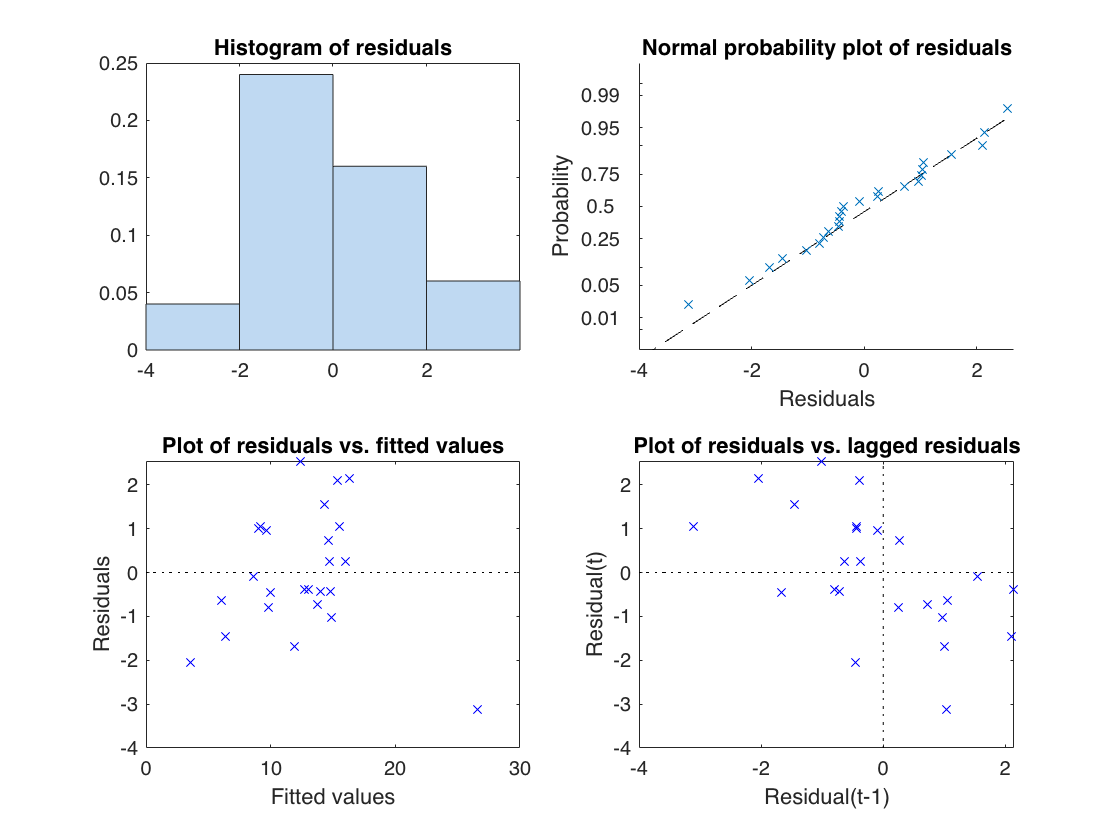

%Checking model assumptions hold for m2 
clf
subplot(2,2,1)
plotResiduals(m2) %plot looks normal 

subplot(2,2,2)
plotResiduals(m2,'probability')%points aligned with line 

subplot(2,2,3)
plotResiduals(m2,'fitted') %variance not so uniform due to presence of outliers

subplot(2,2,4)
plotResiduals(m2,'lagged') % no trend spotted

%Model assumptions hold for m2

%OVERALL EFFECT OF INGREDIENTS (In best model, m2)
% In m2, the effect of Ingredient 1 on response is 0.80098, ttest
% suggests. Given that this model contains just 1 predictor, Ingredient 2
% has no effect on response here in our chosen model.

Making predictions with optimal model

%PREDICTIONS ABOUT GAS EMISSION
Xnew = [22, 0] %Predict for 20mg ingredient 1, 0mg ingredient 2 

Xnew =     22     0


    %Xnew must have the same number of variables (columns) in the same order as the predictor input used to create model
    %Note that Xnew must also contain any predictor variables that are not used as predictors in the fitted model.
ypred = predict(m2,Xnew) %for any prediction to work, X must have 2 columns 

ypred = 20.3647

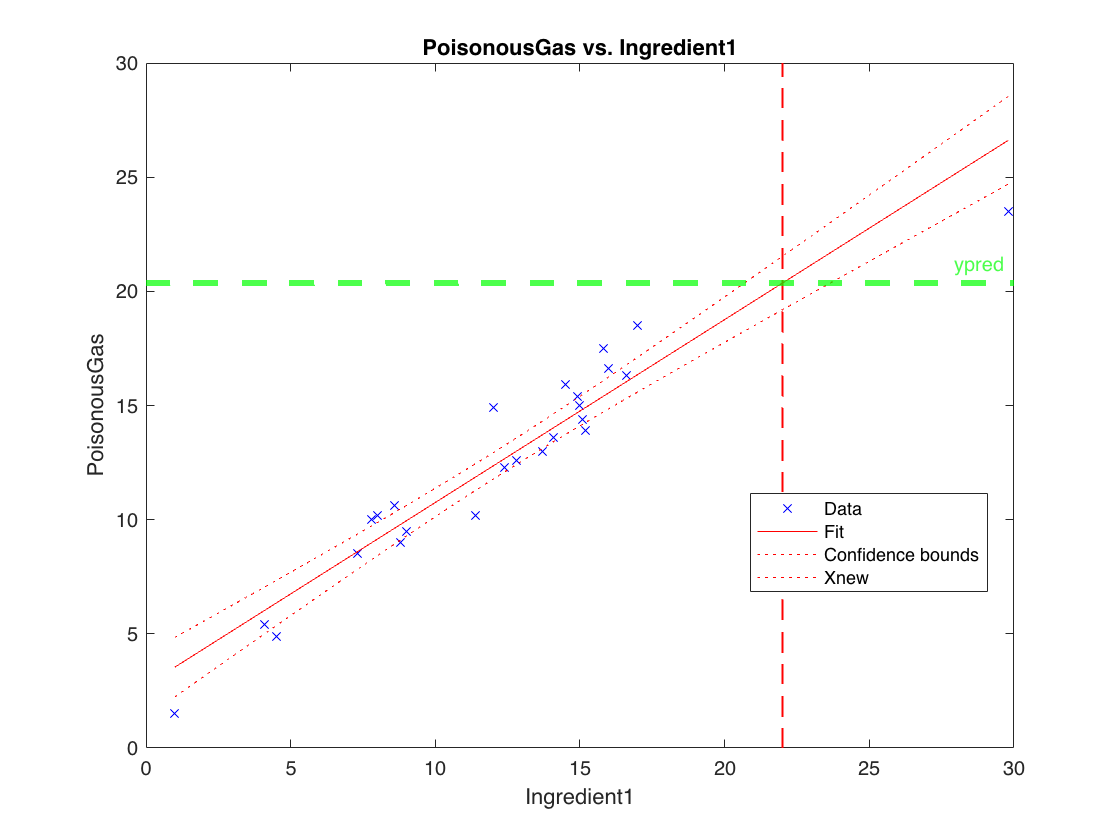

%ypred = 20.3647

clf %plotting a visual representation of predictor and response using model fit to data 
plot(m2)
hold on
line([22, 22],[0,30], 'LineStyle', '--', 'Linewidth', 1,'Color','red');
yline(ypred, 'LineStyle', '--', 'Linewidth', 3,'Color','green', Label='ypred')
legend({'Data','Fit','Confidence bounds','Xnew'})

SUGGESTIONS ON HOW TO IMPROVE EXPERIMENT 

%There are outliers in the data points for Ingredient 1, which may have affected the quality of our model. 
%the outlier showed up in my analysis of the Residuals and fitted values, 
%causing non-uniform variance. Outliers could have been removed or replaced
%by the mean of data points if we didn't want to remove it. 
